clc
clearvars
close all

nlist = readtable("./data/nlist.csv");
elist_dy = readtable("./data/elist_dynamic.csv");

num_edges = size(elist_dy,1);
edges = strings(num_edges,1);
for i=1:num_edges    
    snodes = num2str(elist_dy.Source);
    tnodes = num2str(elist_dy.Target);
    edges(i) = strcat(snodes(i), tnodes(i));
end

endnodes = unique(edges);
num_edges = length(endnodes);
snodes = zeros(num_edges,1);
tnodes = zeros(num_edges,1);

for i=1:num_edges
    split_cha = split(endnodes(i),"");
    snodes(i) = str2double(split_cha(2));
    tnodes(i) = str2double(split_cha(3));
end

weights = ones(length(endnodes),1)*0.1;
etable = table([snodes, tnodes],weights,'VariableNames',{'EndNodes','Weight'});

snodes = elist_dy.Source;
tnodes = elist_dy.Target;
for i=1:size(elist_dy,1)
    s = snodes(i);
    t = snodes(i);
    match_idx = ismember([s,t],etable.EndNodes);


end

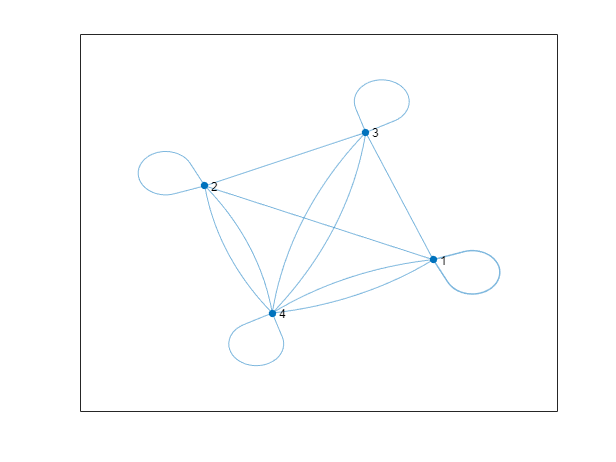

% running_edges
% running_weights
% running_etable

G = graph(etable);
plot(G, 'LineWidth',etable.Weight)